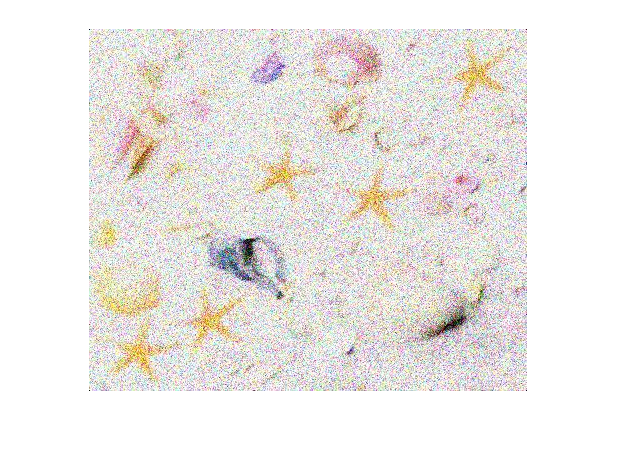

% % % % % % % % % % % % % 

oIm = imread("images\starfish_noise2.jpg");
[ch1, ch2, ch3] = imsplit(oIm);
gIm = rgb2gray(oIm);

% % % % % % % % % % % % % 

im = oIm;

figure
imshow(im)

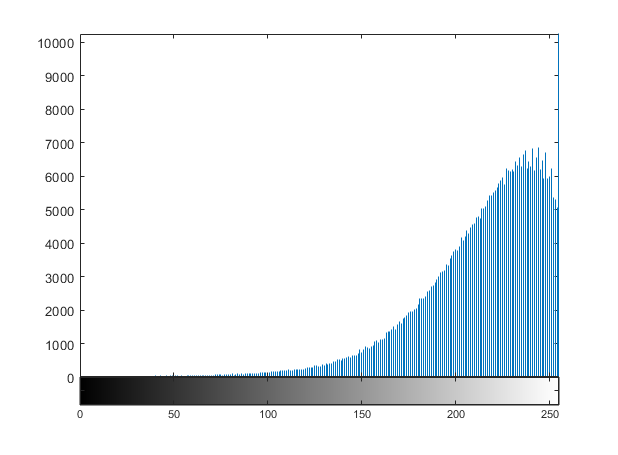

imhist(im)

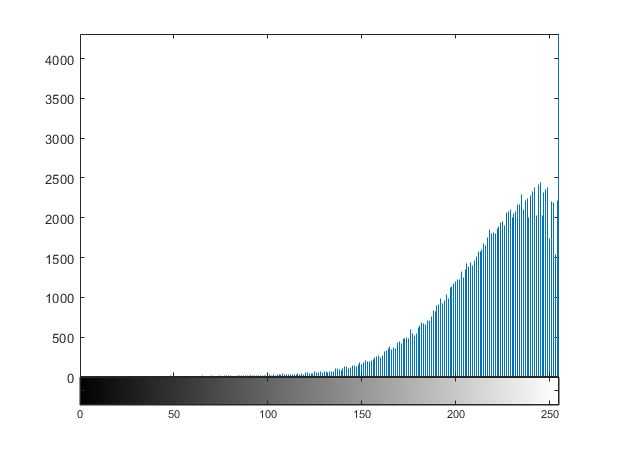

imhist(ch1)

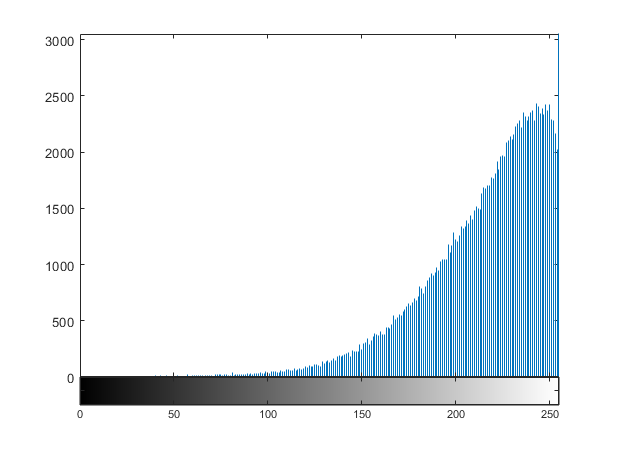

imhist(ch2)

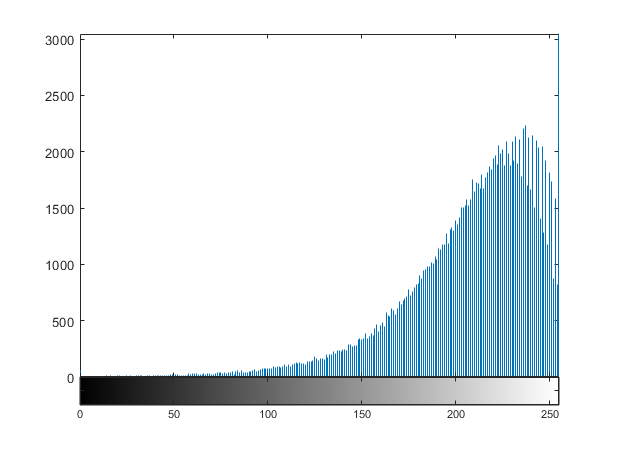

imhist(ch3)

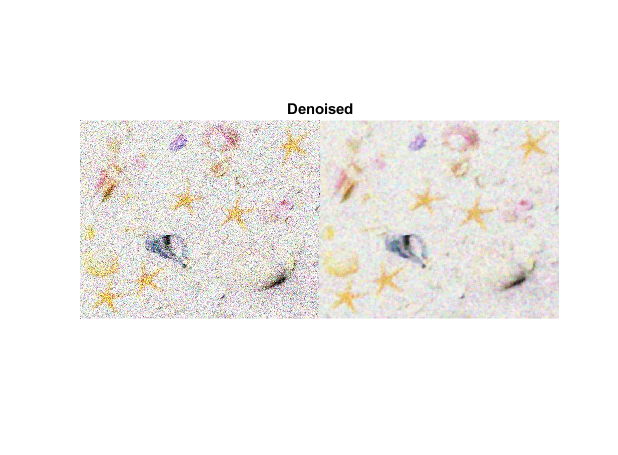


% Denoise
im = medfilt3(im, [5 5 1]);
imshowpair(oIm, im, 'montage')
title("Denoised");

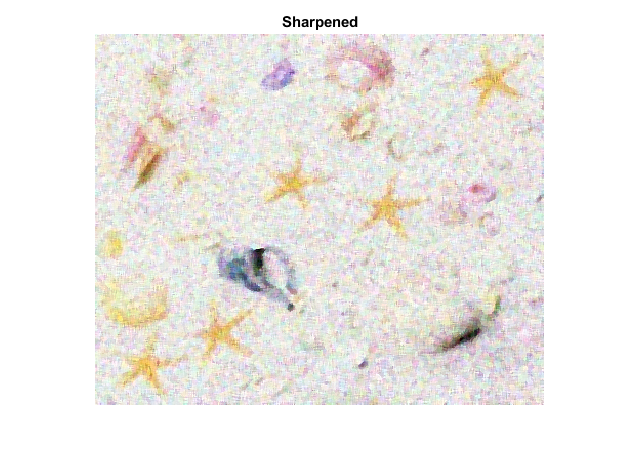


% Sharpen
im = imsharpen(im, 'Radius',1,'Amount',2);
imshow(im)
title("Sharpened");

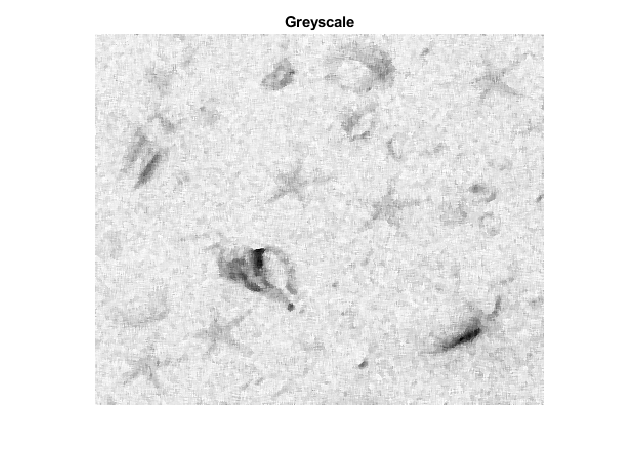


% Greyscale
im = rgb2gray(im);
imshow(im)
title("Greyscale");

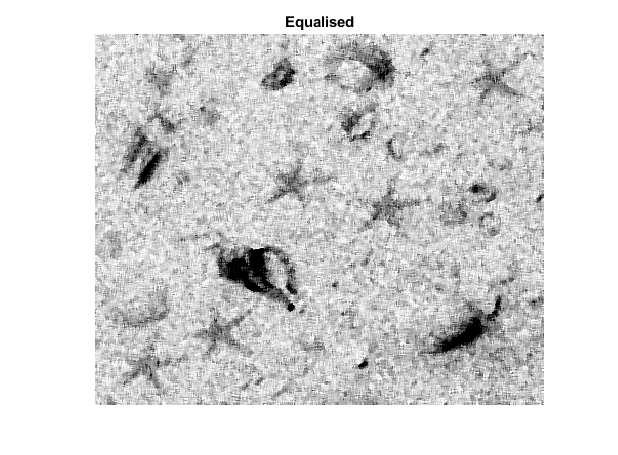


% Equalised
im = imadjust(im);
imshow(im)
title("Equalised");

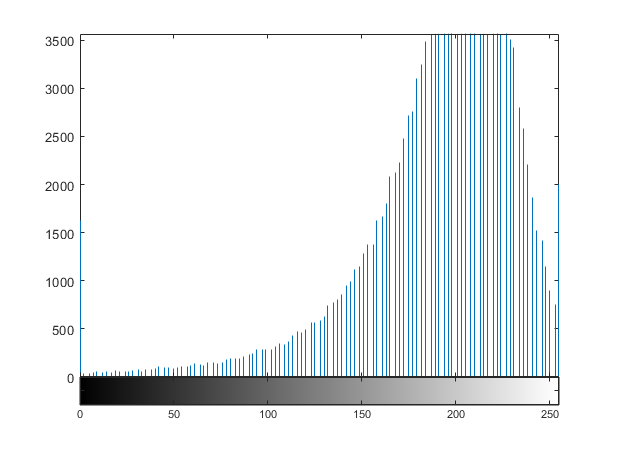

imhist(im)

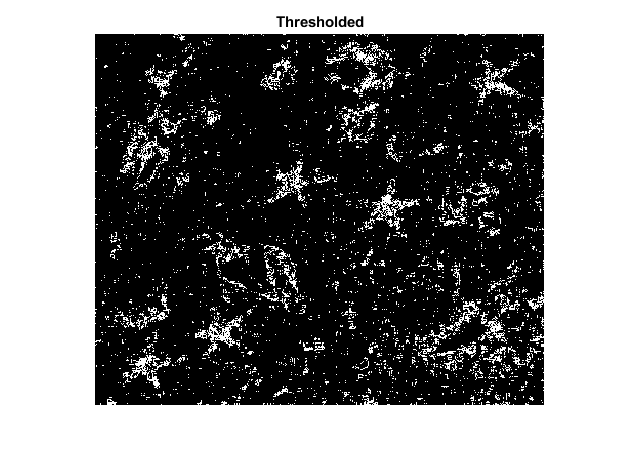


% Threshold
im = Threshold(im, 100, 150);
imshow(im)
title("Thresholded");

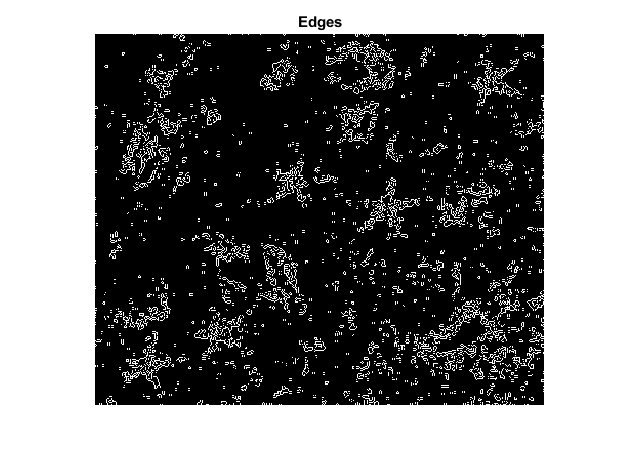


% Detect Edges
im = edge(im);
imshow(im)
title("Edges");

function pIm = Threshold(im, low, high)
    pIm = (im >= low & im <= high);
end
